# **Κεφάλαιο 2: Μηχανές Διανυσματικής Στήριξης: Η Γραμμική Περίπτωση**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Support Vector Machines - Γραμμική Περίπτωση

### Παράδειγμα 1

Δίνονται δύο ισοπίθανες κλάσεις στον δισδιάστατο χώρο, οι οποίες ακολουθούν την κανονική κατανομή. Οι μέσες τιμές είναι $m_1=[0,0]^T, m_2=[1.2, 1.2]^T$ και τα μητρώα συνδιασποράς είναι $S_1=S_2=0.2I$, όπου $I$ είναι ο ταυτοτικός πίνακας $2 \times 2$.

1. Να δημιουργήσετε και να σχεδιάσετε ένα σύνολο δεδομένων $X_1$ το οποίο αποτελείται από $200$ σημεία από κάθε κλάση (σύνολο $400$ σημεία). Το σύνολο αυτό θα χρησιμοποιηθεί στην εκπαίδευση (χρησιμοποιήστε την τιμή $50$ για "σπόρο" στην αρχικοποίηση της MATLAB συνάρτησης randn). Επίσης, δημιουργήστε ένα δεύτερο σύνολο δεδομένων $X_2$ που περιέχει $200$ σημεία από κάθε κλάση και το οποίο θα χρησιμοποιηθεί για δοκιμές (χρησιμοποιήστε την τιμή $100$ ως "σπόρο" στην αρχικοποίηση της MATLAB συνάρτησης randn).

2. Με βάση το $X_1$, τρέξτε τον SVM ταξινομητή για να δημιουργήσετε έξι SVM ταξινομητές που διαχωρίζουν τις δύο κλάσεις, με $C=0.1, 0.2, 0.5, 1, 2, 20$. Να τεθεί $tol=0.001$

     (α) Υπολογίστε το λάθος ταξινόμησης για το σύνολο της εκπαίδευσης και το σύνολο των δοκιμών

    (β) Μετρήστε τα διανύσματα στήριξης

    (γ) Υπολογίστε το περιθώριο $\frac{2}{||w||}$

    (δ) δώστε την γραφική παράσταση του ταξινομητή και των ορίων του περιθωρίου

close('all');
clear;

% Generate and plot X1
randn('seed',50)
m=[0 0; 1.2 1.2]'; % mean vectors
S=0.01*eye(2); % covariance matrix
points_per_class=[200 200];
X1=mvnrnd(m(:,1),S,points_per_class(1))';
X1=[X1 mvnrnd(m(:,2),S,points_per_class(2))'];
y1=[ones(1,points_per_class(1)) -ones(1,points_per_class(2))];

figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bo')

% Generate X2
randn('seed',100)
X2=mvnrnd(m(:,1),S,points_per_class(1))';
X2=[X2 mvnrnd(m(:,2),S,points_per_class(2))'];
y2=[ones(1,points_per_class(1)) -ones(1,points_per_class(2))];

% Generate the required SVM classifier
kernel='linear';
kpar1=0;
kpar2=0;
%C=0.1; 
% C=0.2;
% C= 0.5;
 C=1;
% C=2;
 %C=20;
tol=0.001;
steps=100000;
eps=10^(-10);
method=0;
[alpha, w0, w, evals, stp, glob] = SMO2(X1', y1',kernel, kpar1, kpar2, C, tol, steps, eps, method);

% Compute the classification error on the training set
Pe_tr=sum((2*(w*X1-w0>0)-1).*y1<0)/length(y1)

Pe_tr = 0


% Compute the classification error on the test set
Pe_te=sum((2*(w*X2-w0>0)-1).*y2<0)/length(y2)

Pe_te = 0

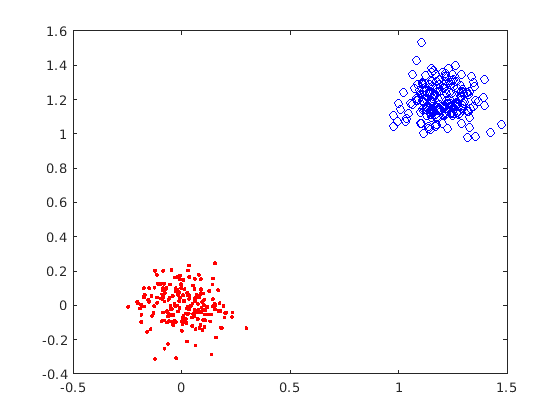

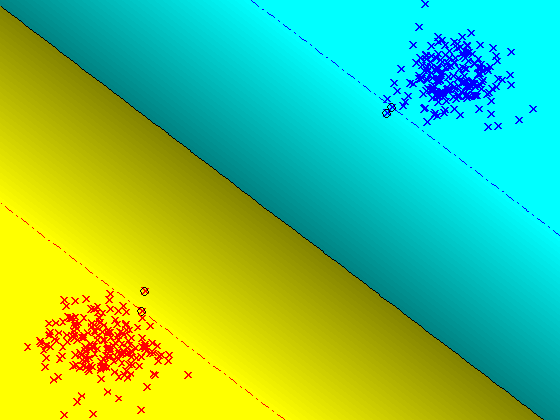


% Plot the classifier hyperplane
global figt4
figt4=2;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,-w0)


% Count the support vectors
sup_vec=sum(alpha>0)

sup_vec = 4


% Compute the margin
marg=2/sqrt(sum(w.^2))

marg = 1.2463

### Άσκηση 1

Να επαναληφθεί το Παράδειγμα, θέτοντας τα μητρώα συνδιασποράς των Gaussian κατανομών ως $S_1=S_2=0.3I$ και να σχολιαστούν τα αποτελέσματα.

## Γενικεύσεις για την περίπτωση πολλών κλάσεων

### Παράδειγμα 1

1. Δημιουργήστε και αποδώστε γραφικά δύο σύνολα δεδομένων, τα $X_1$ (σύνολο εκπαίδευσης) και $X_2$ (σύνολο δοκιμής) χρησιμοποιώντας τη συνταγή του προηγούμενου Παραδείγματος, όπου τώρα το κάθε σύνολο αποτελείται από $120$ σημεία δεδομένων.

2. Με βάση το $X_1$ να γίνει εκτίμηση των διανυσμάτων παραμέτρων $w_1, w_2, w_3$ των τριών γραμμικών συναρτήσεων διάκρισης, χρησιμοποιώντας τους ταξινομητές SVM. Να γίνει εκτίμηση του σφάλματος ταξινόμησης με βάση το $X_2$.

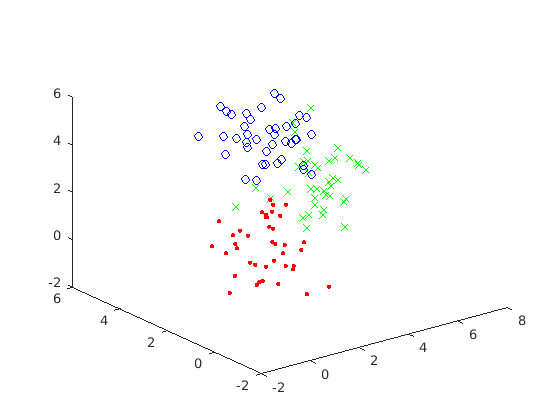

close('all');
clear;

m=[1 1 1; 5 3 2; 3 3 4]';
[l,c]=size(m);
S1=[0.8 0.2 0.1; 0.2 0.8 0.2; 0.1 0.2 0.8];
S(:,:,1)=S1;
S(:,:,2)=S1;
S(:,:,3)=S1;
P=[1/3 1/3 1/3];

% 1. Generate X1
N1=120;
randn('seed',0)
[X1,y1]=generate_gauss_classes(m,S,P,N1);
[l,N1]=size(X1);
X1=[X1; ones(1,N1)];

% Generate X2
N2=120;
randn('seed',100)
[X2,y2]=generate_gauss_classes(m,S,P,N2);
[l,N2]=size(X2);
X2=[X2; ones(1,N2)];

% Generate z1
z1=-ones(c,N1);
for i=1:N1
    z1(y1(i),i)=1;
end

% Generate z2
z2=-ones(c,N2);
for i=1:N2
    z2(y2(i),i)=1;
end

% Plot X1
figure(1), plot3(X1(1,z1(1,:)==1),X1(2,z1(1,:)==1),...
    X1(3,z1(1,:)==1),'r.',X1(1,z1(2,:)==1),X1(2,z1(2,:)==1),...
    X1(3,z1(2,:)==1),'gx',X1(1,z1(3,:)==1),X1(2,z1(3,:)==1),...
    X1(3,z1(3,:)==1),'bo')


% 2. Compute the SVM classifiers
kernel='linear';
kpar1=0;
kpar2=0;
C=0.1;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
for i=1:c
    [alpha(:,i), w0(i), w(i,:), evals, stp, glob] = SMO2(X1', z1(i,:)', kernel, kpar1, kpar2, C,...
        tol, steps, eps, method);
    marg(i)=2/sqrt(sum(w(i,:).^2));
    sup_vec(i)=sum(alpha(:,i)>0);
end

The algorithm has not converged. This may be due to:
 (a) the maximum number of iterations has been reached and convergence has not, yet, been achieved or 
 (b) the chosen values for the hyperparameters (C as well as the parameters that define the kernel function) 
 can not lead to a solution. 


marg,sup_vec

marg =     1.8364    1.9847    5.3091


sup_vec =     21    33     8



% Estimate the classification error based on X2
[vali,class_est]=max(w*X2-w0'*ones(1,N2));
err_svm=sum(class_est~=y2)/N2

err_svm = 0.0750